# CartPole System - LQR Control

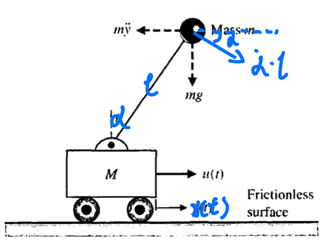

对于一个单自由度倒立摆模型：

- 下方小车质量M

- 上方小球质量m

- 无质量杆长度l

- 摆杆与竖直方向夹角alpha

- x(t)为小球的横向坐标位置

- 系统输入量为作用在小车上的力u(t)

clear
close all
clc

# 线性化之后 - 系统的状态空间模型

% 定义常量
g = 9.81;
m = 1;
l = 1;
M = 1;

A,B,C,D的构建过程请参照“Inverted_Pendulum_Dynamics.mlx”中的动力学方程推导过程

A = [0    1              0    0;
     0    0         -g*m/M    0;
     0    0              0    1;
     0    0 (m*g+M*g)/(M*l)   0]

A =          0    1.0000         0         0
         0         0   -9.8100         0
         0         0         0    1.0000
         0         0   19.6200         0


B = [      0;
         1/M;
           0;
     -1/(M*l)]

B =      0
     1
     0
    -1


C = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = [0; 0; 0; 0] 

D =      0
     0
     0
     0


% 连续状态空间模型
sys_cartpole = ss(A,B,C,D);

# 创建LQR控制器

LQR: Linear Quadratic Regulator

即：线性二次型调节器

“调节器”意味着LQR只适用于调节问题，即期望值必须是0.

% 定义初始状态
% [x x_dot alpha alpha_dot]
x0 = [0 0 10 0];

% Q 和 R 需要不断调试
% Q:运行代价权重矩阵
% [x x_dot alpha alpha_dot]
Q = diag([10 1 100 1])

Q =     10     0     0     0
     0     1     0     0
     0     0   100     0
     0     0     0     1


% R:控制量代价权重矩阵 
R = 1

R = 1.0000e-04

K = lqr(sys_cartpole, Q, R)

K = 1.0e+03 *

   -0.3162   -0.3599   -1.8733   -0.5119


## 构建被LQR控制后的闭环系统模型

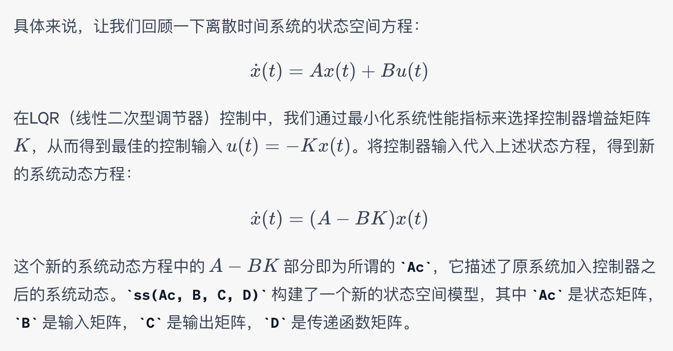

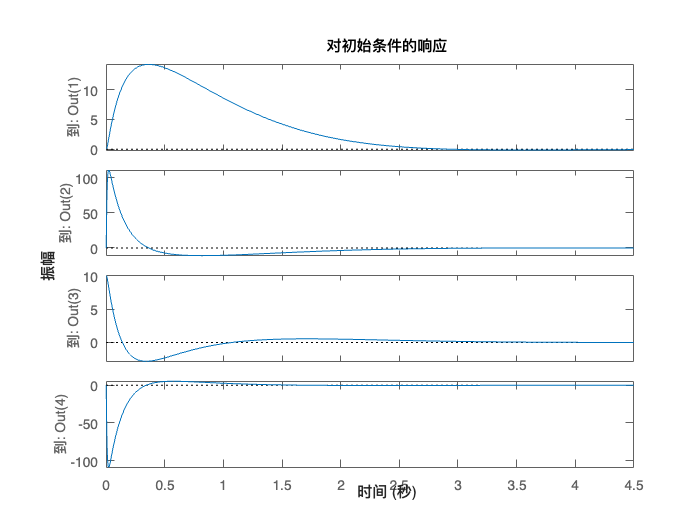

Ac = A - B*K;
sys_cartpole_with_lqr = ss(Ac,[0;0;0;0], C, D);

% 绘制系统初值响应
initial(sys_cartpole_with_lqr,x0)

# 仔细探讨：连续型LQR控制器的求解过程

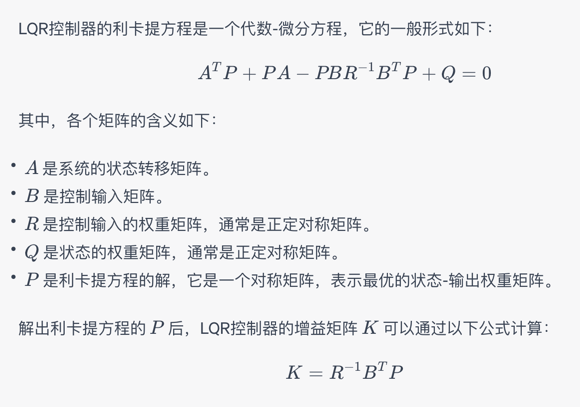

## 根据Riccati方程求解最优增益K

% icare() 用于求解连续性Riccati方程 
[P,L,G] = icare(A,B,Q,R);

K_manual = 1.0e+03 *

   -0.3162   -0.3599   -1.8733   -0.5119


K_manual = inv(R) * B' * P

K = 1.0e+03 *

   -0.3162   -0.3599   -1.8733   -0.5119


K

对比手动计算得到的K_manual 与系统 lqr() 函数求解的K，两者相同。